% Import table
step_Kp15 = readtable("step_Kp15.csv");

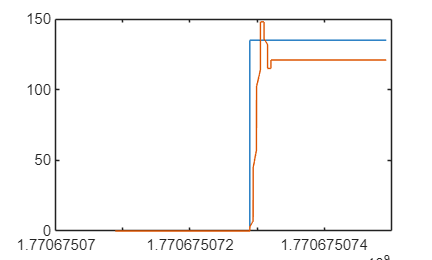

plot(step_Kp15.timestamp, step_Kp15.target, step_Kp15.timestamp, step_Kp15.current);

%% Extract and normalize time
t = step_Kp15.timestamp;
u = step_Kp15.target;
y = step_Kp15.current;

t = t - t(1);                         % start at 0
dt = diff(t);
Ts = median(dt);

% Check sampling jitter (optional but recommended)
jitter = std(dt);
fprintf('Ts = %.6g s, jitter std = %.6g s\n', Ts, jitter);

Ts = 0.000210524 s, jitter std = 0.0226851 s



%% Resample to a uniform time base (recommended)
tq = (0:Ts:t(end)).';                 % uniform time vector
u = interp1(t, u, tq, 'previous', 'extrap');   % ZOH for command
y = interp1(t, y, tq, 'linear',   'extrap');   % linear for measurement
t = tq;

%% Robust step start detection (handles noise)
du = [0; diff(u)];
thr = 0.2 * max(abs(du));             % threshold relative to biggest jump
k0  = find(abs(du) > thr, 1, 'first'); % step index

if isempty(k0)
    error('Could not detect a step change in u.');
end

pre  = 50;                             % samples before step to keep
post = length(t);                      % keep to end (or set a window)
i0 = max(k0 - pre, 1);
i1 = post;

t2 = t(i0:i1);
u2 = u(i0:i1);
y2 = y(i0:i1);

%% Remove offsets using pre-step mean (better than detrend for step tests)
preIdx = 1:min(pre, length(t2));      % the pre-step window in trimmed data
u0 = mean(u2(preIdx));
y0 = mean(y2(preIdx));

u2 = u2 - u0;
y2 = y2 - y0;

data = iddata(y2, u2, Ts);

%% Fit TF models (try a few sensible structures)
opt = tfestOptions;
opt.InitializeMethod = "all";         % helps avoid bad local minima
opt.Display = "off";

sys_tf30 = tfest(data, 3, 0, opt);    % 3 poles, 0 zeros
sys_tf21 = tfest(data, 2, 1, opt);    % 2 poles, 1 zero
sys_tf31 = tfest(data, 3, 1, opt);    % 3 poles, 1 zero
sys_tf32 = tfest(data, 3, 2, opt);    % 3 poles, 2 zeros

%% Inspect and compare
disp('Damping / natural frequencies for 3p1z model:');

Damping / natural frequencies for 3p1z model:


damp(sys_tf31)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -8.90e+00 + 2.15e+01i     3.83e-01       2.33e+01         1.12e-01    
 -8.90e+00 - 2.15e+01i     3.83e-01       2.33e+01         1.12e-01    
 -2.89e+01                 1.00e+00       2.89e+01         3.46e-02    


disp('Zeros of sys_tf31:');

Zeros of sys_tf31:


zero(sys_tf31)

ans = 17.9069

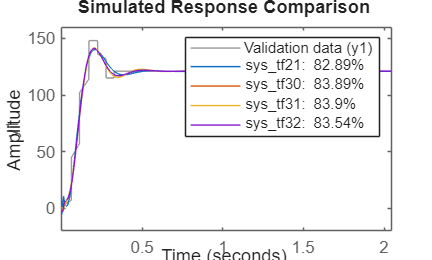


compare(data, sys_tf21, sys_tf30, sys_tf31, sys_tf32);

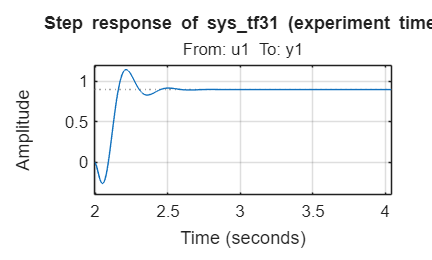

% plot final system sys_tf31
figure;
step(sys_tf31, t2);
grid on;
title('Step response of sys\_tf31 (experiment time)');

%% Tuning the Gains
G = sys_tf31;     % use your chosen plant model
H = 1;            % unity feedback

% Target RCGs
Ts_target  = 0.10;   % seconds
Tr_target = 0.05;    % seconds
OSu_target = 10;     % percent overshoot
Ess_target = 1;      % percent steady-state error

% Derivative filter pole (must be negative)
p = -200;            % try -80 to -800 depending on noise / aggressiveness

% Initial guess (seed)
% Option A: use pidtune as a starting point (recommended)
try
    C0 = pidtune(G, "PID");  % Control System Toolbox
    KIN.K  = 1;
    KIN.Kp = C0.Kp;
    KIN.Ki = C0.Ki;
    KIN.Kd = C0.Kd;
catch
    % Option B: fallback guess
    KIN.K  = 1;
    KIN.Kp = 1;
    KIN.Ki = 1;
    KIN.Kd = 0.01;
end

% Run tuner
Kbest = heurRCGTune_PID(KIN, Ts_target, Tr_target, OSu_target, Ess_target, p, G, H);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           4    8.570342e+02     0.000e+00     1.000e+00     0.000e+00     5.159e+04  
Objective function returned Inf; trying a new point...
    1          40    8.450145e+02     0.000e+00     1.104e-05     1.157e-02     6.193e+04  
Objective function returned Inf; trying a new point...
    2          81    8.409795e+02     0.000e+00     1.856e-06     4.092e-03     6.836e+04  
Objective function returned Inf; trying a new point...
    3         127    8.402974e+02     0.000e+00     3.120e-07     6.877e-04     6.946e+04  
Objective function returned Inf; trying a new point...
    4         182    8.402699e+02     0.000e+00     1.259e-08     2.775e-05     6.951e+04  
Objective function returned Inf; trying a new point...
    5         241    8.402632e+02     0.000e+00     3.023e-09     6.663e-06     6.9


Kp = Kbest(1); Ki = Kbest(2); Kd = Kbest(3);
fprintf('\nTUNED GAINS:\nKp = %.6g\nKi = %.6g\nKd = %.6g\n', Kp, Ki, Kd);


TUNED GAINS:
Kp = 0.000120601
Ki = 4.43077
Kd = 0



% Build controller + show closed-loop step
s = tf('s');
D   = Kp + Ki/s + Kd * (-p*s/(s - p));     % same form as tuner
Tcl = feedback(G*D, H);

%{
    Testing with different gains. Found gains:
    Kp = 0.000120601
    Ki = 4.43077
    Kd = 0
%}
Kp_test = 0.000120601

Kp_test = 1.2060e-04

Ki_test = 5.43077

Ki_test = 5.4308

Kd_test = 0.0

Kd_test = 0

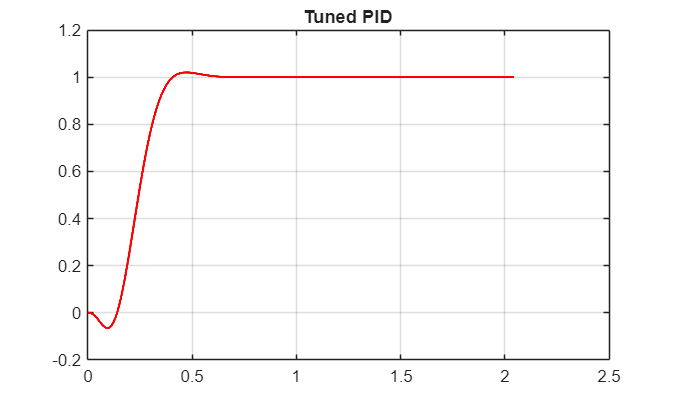


D_test   = Kp_test + Ki_test/s + Kd_test * (-p*s/(s - p));     % same form as tuner
Tcl_test = feedback(G*D_test, H);

% Use 0-based time axis
t_plot = t2 - t2(1);

% Get step responses
y_found = step(Tcl, t_plot);
y_test  = step(Tcl_test, t_plot);

% Plotting tuned PID
figure;
plot(t_plot, y_found, '-r', 'LineWidth', 1.5);
title('Tuned PID');
grid on;

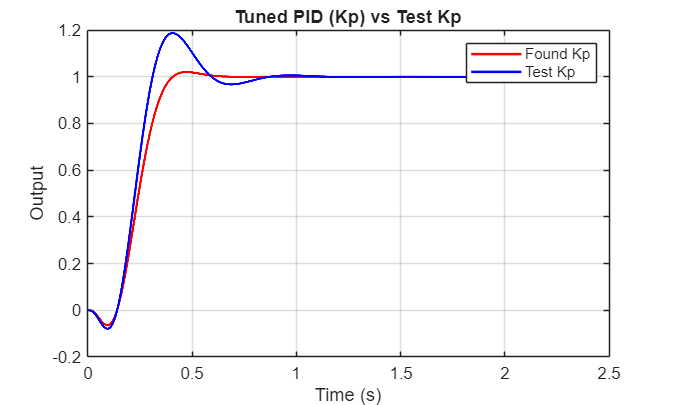


% Plotting comparison
figure;
plot(t_plot, y_found, '-r', 'LineWidth', 1.5); hold on;
plot(t_plot, y_test,  '-b', 'LineWidth', 1.5);
grid on;

xlabel('Time (s)');
ylabel('Output');
title('Tuned PID (Kp) vs Test Kp');
legend('Found Kp', 'Test Kp');


% Step response metrics
info = stepinfo(Tcl, 'RiseTimeLimits', [0 1]);
Ess  = abs(1 - dcgain(Tcl))*100;
fprintf('Closed-loop metrics: Ts=%.4f s, OS=%.2f%%, Tr=%.4f s, Ess=%.3f%%\n', ...
    info.SettlingTime, info.Overshoot, info.RiseTime, Ess);

Closed-loop metrics: Ts=0.3869 s, OS=2.00%, Tr=0.2678 s, Ess=0.000%


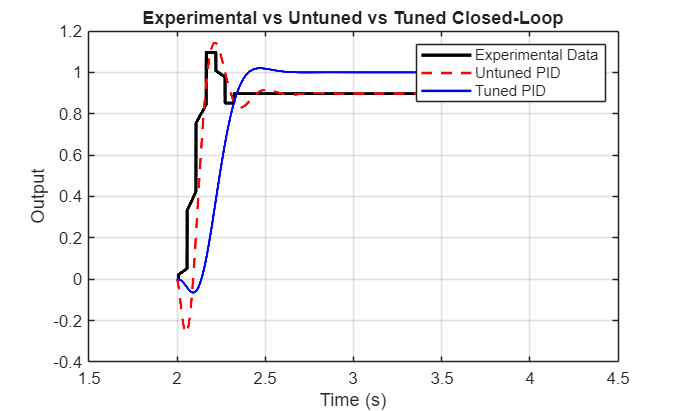

% Compare Experimental vs Untuned vs Tuned

% Applying step
t_sim = t2;   
y_untuned = step(sys_tf31, t_sim);
y_tuned   = step(Tcl, t_sim);

% Experimental output (already offset removed)
y_exp = y2;

% Normalize experimental step amplitude to 1 (if needed)
% Only do this if your command step is ~1 unit
u_amp = max(u2) - min(u2);
if u_amp ~= 0
    y_exp = y_exp / u_amp;
end

%% Plot Comparison
figure;
plot(t_sim, y_exp, 'k', 'LineWidth', 2); hold on;
plot(t_sim, y_untuned, '--r', 'LineWidth', 1.5);
plot(t_sim, y_tuned, '-b', 'LineWidth', 1.5);
grid on;

xlabel('Time (s)');
ylabel('Output');
title('Experimental vs Untuned vs Tuned Closed-Loop');
legend('Experimental Data', 'Untuned PID', 'Tuned PID');